clear;
clc;

% Lapso temporal
t = linspace(0, 3e4, 1e6);

% Constantes (SSO)
mu = 3.986004418e14;
J3 = - 2.532435346e-6;
R = 6378.137e3;
a = 7211.54e3;
n = sqrt(mu ./ a.^3);
INC     = deg2rad(98.7);
omega   = deg2rad(30);
theta_0 = deg2rad(45);

% Condiciones iniciales
x0  = 0;
y0  = 0;
z0  = 0;
dx0 = 0;
dy0 = 0;
dz0 = 0;

% Identidades trigonométricas
nt = n.*t;
cnt = cos(nt);
snt = sin(nt);
c2nt = cos(2.*nt);
s2nt = sin(2.*nt);
c3nt = cos(3.*nt);
s3nt = sin(3.*nt);

si = sin(INC);
ci = cos(INC);
sw = sin(omega);
cw = cos(omega);
s2w = sin(2.*omega);
c2w = cos(2.*omega);
s3w = sin(3.*omega);
c3w = cos(3.*omega);

% Constantes de Kéchichian
k1 = - n.^2.*J3.*R.^3./(2.*a.^2);
k2 = 15./4.*si.^3 - 3 .* si;
k3 = 15./4.*si.^3;
K3 = dy0 + 2.*n.*x0 - (k1.*k2.*sw./n) + (k1.*k3.*s3w./(3.*n));
kp3  = dx0 ./ n;
kpp3 = x0;
Kp3  = y0 - 2.*dx0./n - 5.*J3.*R.^3./(2.*a.^2) .* ...
       (15./4.*si.^3.*(cw - c3w./9) - 3.*cw.*si);
m1 = ci .* (15./2.*si.^2 - 3);
m2 = 15./2.*si.^2.*ci;
cp3  = dz0./n;
cpp3 = z0;

% Constantes de la memoria
eta   = nt/2;
alpha1  =     omega +   theta_0;
alpha2  =   2*omega +   theta_0;
alpha3  =   2*omega + 3*theta_0;
alpha4  =     omega + 2*theta_0;
alpha5  =     omega + 3*theta_0;
alpha6  =     omega -   theta_0;


beta1   =       eta +    alpha1;
beta2   =     3*eta +  2*alpha1;
beta3   =       eta +  2*alpha1;
beta4   =       eta -  2*alpha1;
beta5   =     - eta +    alpha1;
beta6   =     2*eta +    alpha1;
beta7   =     3*eta +    alpha1;
beta8   =    -  eta +    alpha1;
beta9   =   - 2*eta +    alpha1;

beta10  =     2*eta +    alpha2;
beta11  =     4*eta +    alpha2;
beta12  =   - 2*eta +    alpha2;

beta13  =    2*eta +    alpha3;
beta14  =    6*eta +    alpha3;
beta15  =  - 2*eta +    alpha3;

beta16  =      eta +    alpha4;
beta17  =    2*eta +    alpha4;
beta18  =    3*eta +    alpha4;
beta19  =    4*eta +    alpha4;
beta20  =    - eta +    alpha4;
beta21  =  - 2*eta +    alpha4;

beta22  =     2*eta +    alpha5;
beta23  =     4*eta +    alpha5;
beta24  =   - 2*eta +    alpha5;

beta25  =     2*eta +    alpha6;
beta26  =     2*eta -    alpha6;


tau1    =     2*eta +   theta_0;
tau2    =   - 2*eta +   theta_0;
o1      =       eta +     omega;
o2      =     2*eta +     omega;
o3      =     - eta +     omega;
o4      =   - 2*eta +     omega;
kappa_i = 3*cos(2*INC) + 1;
zeta_i  = sin(INC) + 5*sin(3*INC);
zeta_a1 = sin(alpha1) + 5*sin(3*alpha1);

u = beta6;

% Solución analítica
xJ3B = (1 + 6*sin(eta).^2).*x0 ...
        + (sin(2*eta)./n).*dx0 ...
        - (4/n)*sin(eta).*dy0 ...
        + (3*n*R^3*J3/32/a^2).*t.*cos(u).* ( ...
                sin(INC) + 5.*sin(3*INC) ...
        ) ...
        + (R^3*J3/32/a^2) .* ( ...
            -3*sin(2*eta).*( ...
                  5*sin(INC)^3*cos(3*alpha1) ...
                + (sin(INC) + 5*sin(3*INC))*cos(alpha1) ...
            ) ...
            + cos(2*eta).*( ...
                35*sin(INC)^3*sin(3*alpha1) ...
                + 6*sin(alpha1)*(sin(INC) + 5*sin(3*INC))...
            ) ...
            + 5*sin(3*u)*sin(INC)^3 ...
            - 2*( ...
                20*sin(3*INC)*sin(alpha1)^3 ...
                + 3*sin(INC)*(sin(alpha1) + 5*sin(3*alpha1))...
            ) ...
        );
xJ3K = kp3.*snt + kpp3.*cnt - k1.*k2./n .* ...
       (-cw.*cnt.*t + sw.*snt.*t + cw.*snt./n) + ...
       k1.*k3./(6.*n.^2) .* ...
       (-s3w./2.*c3nt + s3w./2.*cnt - c3w./2.*s3nt + 3./2.*c3w.*snt) + ...
       2.*K3./n .* (1 - cnt);

xdotJ3B = 3.*n.*sin(2*eta).*x0 ...
        + cos(2*eta).*dx0 ...
        + 2.*sin(2*eta).*dy0 ...
        - (n.*R.^3.*J3)./32/(a^2) .* ( ...    
            15*cos(3*beta9).*sin(INC).^3 ...
            + 15.*cos(2*eta)*cos(3*alpha1).*sin(INC).^3 ...
            + sin(2*eta).*( ...
                35*sin(3*alpha1).*sin(INC).^3 ...
                + 9*sin(alpha1).*(sin(INC) + 5*sin(3*INC)) ...
             ) ...
            + 6*eta.*sin(u).*(sin(INC) + 5*sin(3*INC)) ...
        );
xdotJ3K = n.*kp3.*cnt - n.*kpp3.*snt - k1.*k2./n .* ...
          (cw.*nt.*snt + sw.*snt + sw.*nt.*cnt) + ...
          k1.*k3./(6 .* n.^2) .* ...
          (3.*n./2.*s3w.*s3nt - n./2.*s3w.*snt - 3.*n./2.*c3w.*c3nt + 3.*n./2.*c3w.*cnt) + ...
          2.*K3.*snt;

yJ3B = 6*sin(n.*t).*x0 + y0 ...
        - (4./n).*sin(eta).^2.*dx0 ...
        + (4./n).*sin(n.*t).*dy0 ...
        - (6*n.*x0 + 3*dy0 - (3*n.*R.^3.*J3)./(32*a.^2) .* ( ...
            20.*sin(3*INC).*sin(alpha1).^3 ...
            + 3.*sin(INC).*(sin(alpha1) + 5*sin(3*alpha1)) ...
            - 2.*sin(u).*(sin(INC) + 5*sin(3*INC)) ...
        )).*t ...
        - (R.^3.*J3)./(192*a.^2) .* ( ...
            6.*sin(2*eta).*(70.*sin(INC).^3.*sin(3*alpha1) + 3.*sin(alpha1).*(sin(INC) + 5*sin(3*INC))) ...
            + 45.*cos(2*eta).*(3.*cos(3*alpha1).*(sin(INC) - sin(3*INC)) + 2.*cos(alpha1).*(sin(INC) + 5*sin(3*INC))) ...
            - 20.*sin(6*eta).*sin(3*alpha1).*sin(INC).^3 ...
            + 15.*cos(6*eta).*(4.*cos(3*alpha1).*sin(INC).^3 + cos(3*omega).*cos(3*theta_0).*(sin(INC) - sin(3*INC))) ...
            - 10.*( ...
                3.*sin(INC).*cos(alpha1).*(30.*cos(2*INC) + 10.*cos(2*alpha1) + 13) ...
                -5.*sin(3*INC).*sin(3*omega).*(cos(3*omega) - 5.*sin(3*theta_0)) ...
            ) ...
        );
yJ3K = 2.*kp3.*cnt - 2.*kpp3.*snt + ...
      k1.*k2.*(- 2.*t./n.*cw.*snt - 2.*t./n.*sw.*cnt + 3.*sw./n.^2.*snt - 5.*cw./n.^2.*cnt) - ...
      k1.*k3./(6.*n.^2) .* ...
      (s3w.*snt - 3.*c3w.*cnt + s3w./3.*s3nt - c3w./3.*c3nt) - ...
      3.*K3.*t + 4.*K3./n.*snt + Kp3;

ydotJ3B = -12.*n.*sin(eta).^2.*x0 ...
            - 2.*sin(n.*t).*dx0 ...
            + (1 - 8.*eta.^2).*dy0 ...
            + n*R^3*J3/32/a^2.*( ...
            + 2*sin(2*eta).*( ...    
                + 15*sin(INC).^3*cos(3*alpha1) ...
                + 3*cos(alpha1)*(9*sin(INC) + 5*sin(3*INC)) ...
                - 40*sin(2*eta).^2.*cos(alpha1).^3.*sin(INC).^3 ...
                ) ...
            + 2*cos(2*eta).*sin(INC).*( ...    
                - 35*sin(INC).^2*sin(3*alpha1) ...
                - 12*sin(alpha1)*(2*cos(2*INC) + kappa_i) ...
                - 40*cos(2*eta).^2.*sin(INC).^2.*sin(alpha1).^3 ...
                ) ...
            - 10*sin(3*u).*sin(INC).^3 ...
            ...
            - 60.*sin(u).*sin(4*eta).*sin(2*alpha1).*sin(INC)^3 ...
            ...
            + 60*sin(3*alpha1)*sin(INC)^3 ...
            + 9*sin(alpha1)*(sin(INC) + 5*sin(3*INC)) ...
            ...
            - 12*eta.*cos(u).*(sin(INC) + 5*sin(3*INC)) ...
            );
ydotJ3K = -2.*n.*kp3.*snt - 2.*n.*kpp3.*cnt + ...
          k1.*k2 .* (-2.*cw.*t.*cnt + 2.*t.*sw.*snt + sw./n.*cnt + 3.*cw./n.*snt) - ...
         (k1.*k3./(3.*n)) .* ...
         (s3w./2.*cnt + 3./2.*c3w.*snt + s3w./2.*c3nt + c3w./2.*s3nt) - ...
         3.*K3 + 4.*K3.*cnt;

zJ3B = cos(2*eta).*z0 + (sin(2*eta)./n).*dz0 ...
        + (R.^3.*J3)/4./a.^2.*sin(eta).^2.* ( ...
            6*(5.*cos(INC).^2 - 3).*cos(INC) ...
            + 5.*sin(2*INC).*sin(INC).*( ...
                2*cos(2*beta1) + cos(2*alpha1) ...
            ) ...
        );
zJ3K = cp3.*snt + cpp3.*cnt + ...
      k1.*m1./n.^2.*(1 - cnt) - k1.*m2./n.^2 .* ...
      (c2w.*(1./3.*cnt - c2nt./3) - s2w.*(2./3.*snt - 1./3.*s2nt));

zdotJ3B = -n.*sin(n.*t).*z0 + cos(n.*t).*dz0 ...
        + (n.*R.^3.*J3)./8/a.^2 .* ( ...
            + sin(2*eta).*cos(INC).*( ...
                -10*sin(INC).^2.*cos(2*alpha1) ...
                + 15*cos(2*INC) ...
                - 3 ...
            ) ...
            - 5*cos(2*eta).*sin(2*alpha1).*( ...
                cos(INC) - cos(3*INC) ...
            ) ...
            + 5*sin(2*u).*( ...
                cos(INC) - cos(3*INC) ...
            ) ...
        );
zdotJ3K = cp3.*n.*cnt - cpp3.*n.*snt + ...
          k1.*m1./n .* snt - k1.*m2./n .* ...
          (c2w .* (- 1./3.*snt + 2./3.*s2nt) - ...
          s2w .* (2./3.*cnt - 2./3.*c2nt));

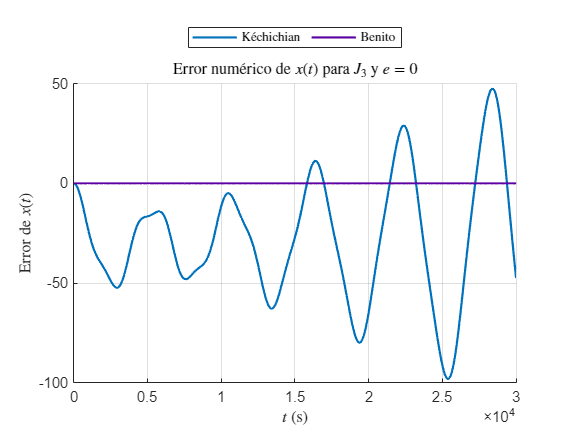

% Resolución
X0 = [x0, y0, z0, dx0, dy0, dz0];

opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-5);
[~, dXdt] = ode113(@(tOde, X) odeClohessyWiltshireJ2J3(tOde, X, 0, J3, R, a, n, INC, omega, theta_0), t, X0, opts);
    
% Comparación
plotNumericErrors(   xJ3K',    xJ3B', dXdt(:, 1), t, 'K\''echichian', 'Benito', ...
          'Error num\''erico de $x(t)$ para $J_3$ y $e = 0$', '$t$ (s)',       'Error de $x(t)$', '#0072BD', '#5C00A3');

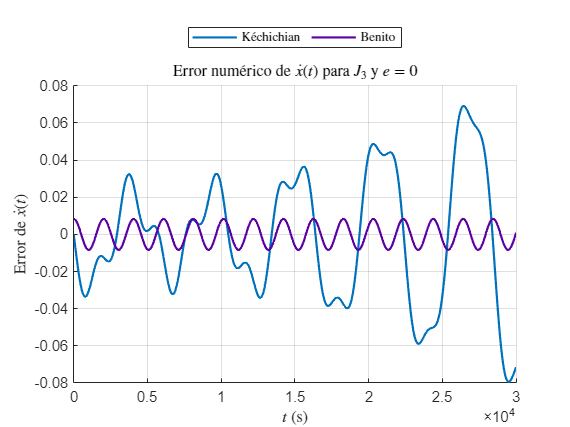

plotNumericErrors(xdotJ3K', xdotJ3B', dXdt(:, 4), t, 'K\''echichian', 'Benito', ...
    'Error num\''erico de $\dot{x}(t)$ para $J_3$ y $e = 0$', '$t$ (s)', 'Error de $\dot{x}(t)$', '#0072BD', '#5C00A3');

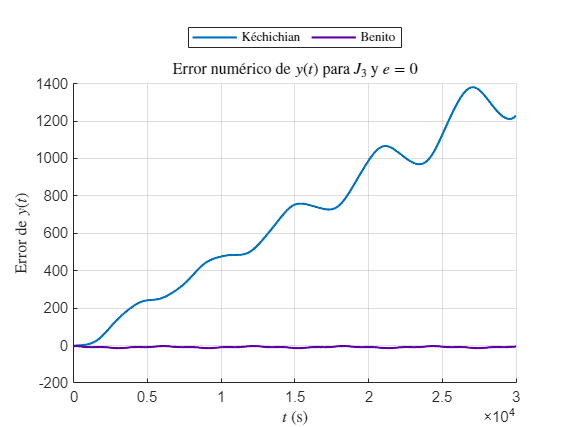

plotNumericErrors(   yJ3K',    yJ3B', dXdt(:, 2), t, 'K\''echichian', 'Benito', ...
          'Error num\''erico de $y(t)$ para $J_3$ y $e = 0$', '$t$ (s)',       'Error de $y(t)$', '#0072BD', '#5C00A3');

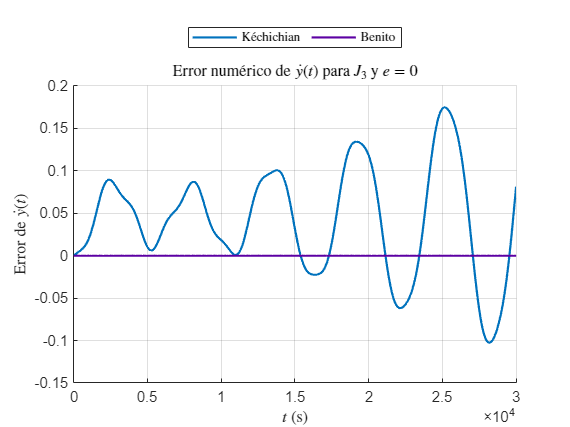

plotNumericErrors(ydotJ3K', ydotJ3B', dXdt(:, 5), t, 'K\''echichian', 'Benito', ...
    'Error num\''erico de $\dot{y}(t)$ para $J_3$ y $e = 0$', '$t$ (s)', 'Error de $\dot{y}(t)$', '#0072BD', '#5C00A3');

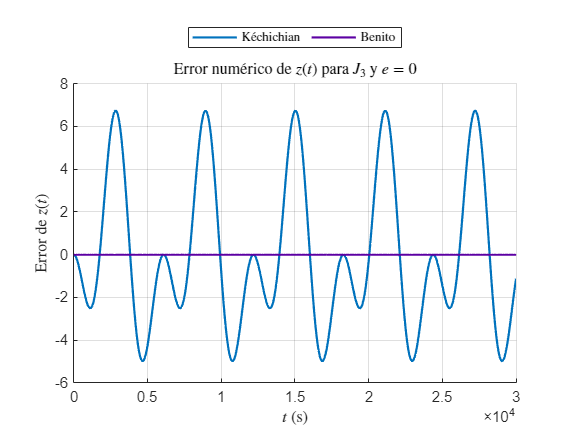

plotNumericErrors(   zJ3K',    zJ3B', dXdt(:, 3), t, 'K\''echichian', 'Benito', ...
          'Error num\''erico de $z(t)$ para $J_3$ y $e = 0$', '$t$ (s)',       'Error de $z(t)$', '#0072BD', '#5C00A3');

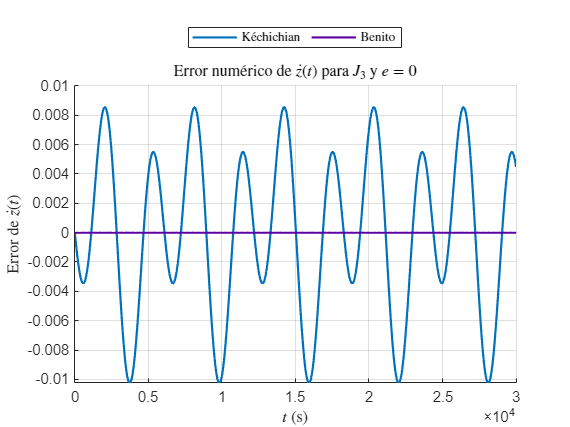

plotNumericErrors(zdotJ3K', zdotJ3B', dXdt(:, 6), t, 'K\''echichian', 'Benito', ...
    'Error num\''erico de $\dot{z}(t)$ para $J_3$ y $e = 0$', '$t$ (s)', 'Error de $\dot{z}(t)$', '#0072BD', '#5C00A3');

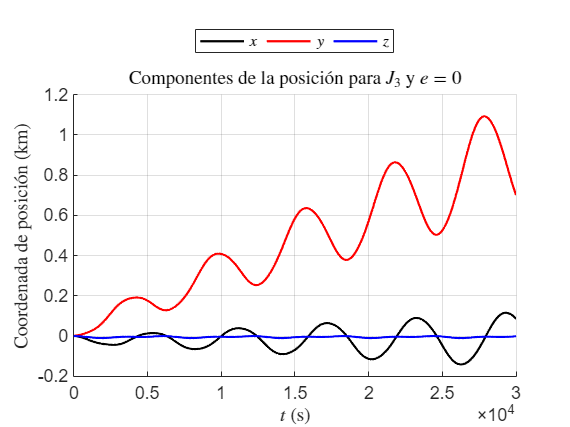




plotMultiComparisons({xJ3B / 10^3, yJ3B / 10^3, zJ3B / 10^3}, t, 'Componentes de la posici\''on para $J_3$ y $e = 0$', ...
    {'Coordenada de posici\''on (km)', '$t$ (s)'},  {'$x$', '$y$', '$z$'}, {'k', 'r', 'b'});

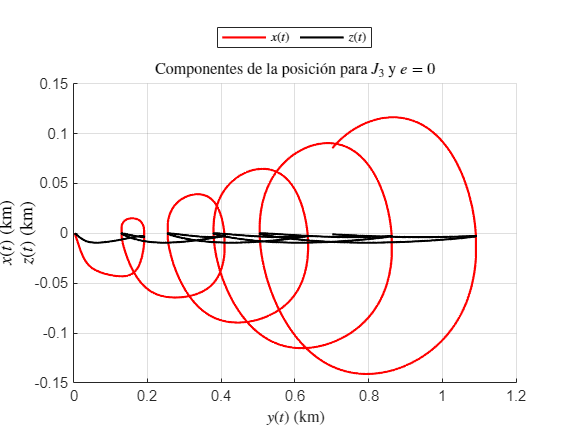

plotComparisons({yJ3B / 10^3, xJ3B / 10^3, zJ3B / 10^3}, {'$y(t)$ (km)', '$x(t)$ (km)', '$z(t)$ (km)'}, ...
   'Componentes de la posici\''on para $J_3$ y $e = 0$', {'$x(t)$', '$z(t)$'}, {'r', 'k'});

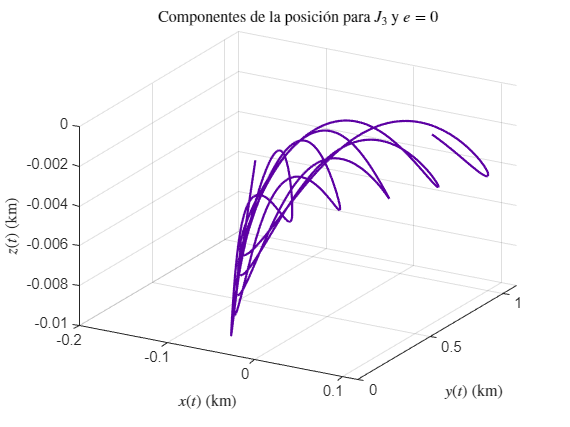

plot3D({xJ3B / 10^3, yJ3B / 10^3, zJ3B / 10^3}, [389.7753 28.6133], ...
    'Componentes de la posici\''on para $J_3$ y $e = 0$', ...
    {'$x(t)$ (km)', '$y(t)$ (km)', '$z(t)$ (km)'}, '#5C00A3');